% Subject list
sn={'S01';'S02';'S04';'S05';'S06';'S07';'S08';'S09';'S10'
    'S11';'S12';'S13';'S14';'S15';'S16';'S17';'S18';'S19';'S20'
    'S21';'S22';'S23';'S24';'S25';'S26';'S27';'S29';'S30'}; % Subjects 3 and 28 exluded due to spinal pathologies
% sn={'S03'};
% Trial list
tn={'Flex_1';       'Flex_2';       'Flex_3'        % 1-3
    'Flex_box_1';   'Flex_box_2';   'Flex_box_3'    % 4-6
    'ExBa_Flex_1';  'ExBa_Flex_2';  'ExBa_Flex_3'   % 7-9
    'Flex_L_1';     'Flex_L_2';     'Flex_L_3'      % 10-12
    'Box_L_1';      'Box_L_2';      'Box_L_3'       % 13-15
    'Flex_R_1';     'Flex_R_2';     'Flex_R_3'      % 16-18
    'Box_R_1';      'Box_R_2';      'Box_R_3'       % 19-21
    'Ext_N_1';      'Ext_N_2';      'Ext_N_3'       % 22-24
    'ExBa_Ext_1';   'ExBa_Ext_2';   'ExBa_Ext_3'    % 25-27
    'Ext_L_1';      'Ext_L_2';      'Ext_L_3'       % 28-30
    'Ext_R_1';      'Ext_R_2';      'Ext_R_3'       % 31-33
    'ExBa_Cont_1';  'ExBa_Cont_2';  'ExBa_Cont_3'   % 34-36
    'SideL_1';      'SideL_2';      'SideL_3'       % 37-39
    'SideR_1';      'SideR_2';      'SideR_3'       % 40-42
    'RotationL_1';  'RotationL_2';  'RotationL_3'   % 43-45
    'RotationR_1';  'RotationR_2';  'RotationR_3'   % 46-48
    'UpnGo_1';      'UpnGo_2';      'UpnGo_3'};     % 49-51
% Exercise list
en={'Flex';'Flex_box';'ExBa_Flex';'Flex_L';'Box_L';'Flex_R';'Box_R';'Ext_N';...
    'ExBa_Ext';'Ext_L';'Ext_R';'ExBa_Cont';'SideL';'SideR';'RotationL';'RotationR';...
    'UpnGo'};

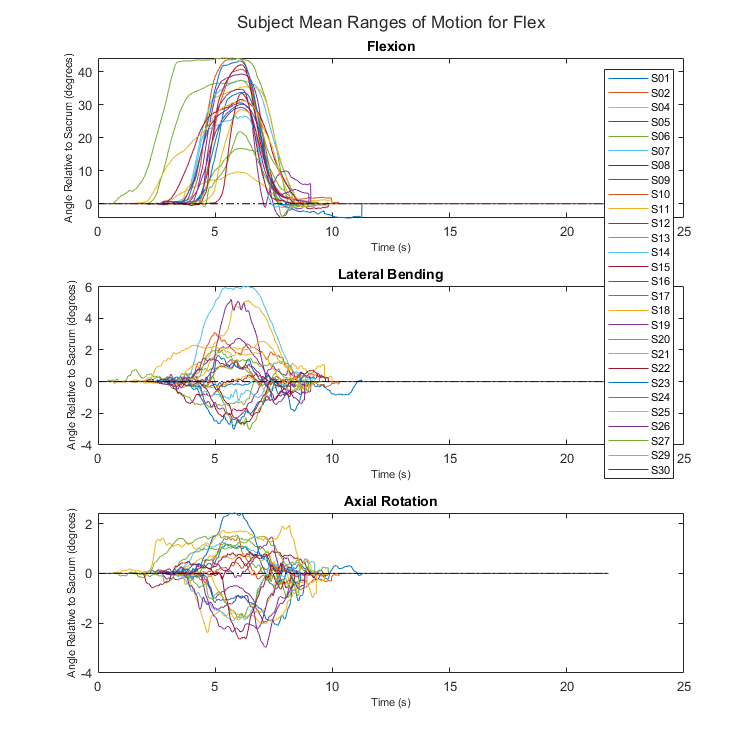

% MAKE SURE TO UPDATE THE PATHS TO REFLECT WHERE YOU HAVE THE FILES SAVED

% Specify folder where the RoMK_F.m function is saved
% addpath('C:\Users\gelde\Documents\BACPAC\MATLAB'); % Local path
addpath('C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Matlab Code\Range of Motion'); % Box path

% This just for convenience so I don't have to have this ridiculously long
% filepath anywhere in the main body of the code
BasePath='C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\RoM\';
Path2='C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\RoM\0_TimeSeries\';
% Path3='C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\RoM\0_KinFigs\';
Path3='C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\RoM\0_CombinedFigures\';
Path4='C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\RoM\0_AllSub\';

FlexRange=nan(3,6,28,2); % initialize FlexRange (holds max/min for each saggital exercise)
LatRange=nan(3,6,28,2); % initialize LatRange (holds max/min for the coronal exercises)
AxialRange=nan(3,6,28,2); % initialize AxialRange (holds max/min for each axial exercise)
RoM=nan(length(en),12,3); % Initialize Range of Motion matrix (exercise,segment(each twice),axis)
ErrR=nan(length(en),2,3); % Initialize error bar array (exercise, pos/neg,axis)

for ie=1:17 % Iterate through each exercise
% for ie=[5] % Iterate through selected exercises
    % Specify the exercise's output folder:
    OutputFolder=strcat(BasePath,en{ie});
    cd(OutputFolder); % Set output folder
    fn=0; % reset file counter
    nst=zeros(89,1); % reset total sample counter
    ipeak=zeros(89,1); % reset the array holding max deflection time
    romL=nan(3,2,30); romT=nan(3,2,30);
    Fsize=8; % Set font sixe in figures
    for j=1:length(sn) % Do this for each subject
        for i=3*ie-2:3*ie % Iterate through each trial of the exercise
            % Run calcuations and save files
            if isfile([sn{j} '_' tn{i} '_Data.mat'])
                load([sn{j} '_' tn{i} '_Data.mat']);
                fn=fn+1; % count number of files successfully read
                ipeak(fn)=sm; % Keep track of the point at which each trial saw its maximum deflection
                nst(fn)=ns; % Keep track of the number of frames/samples in each trial
            end
        end
    end
    ipeak=ipeak(1:fn); % Cut off unused portion of array
    ipeakm=max(ipeak); % Get time step of latest occurring peak
    nst=nst(1:fn); % Cut off unused portion of array
    nstdif=nst-ipeak; % Get time length from peaks to end
    nstm=max(nstdif)+ipeakm; % Get maximum time series length after peak alignment
    APos=nan(nstm,3,6,length(sn),3); % Initialize the position array (frame, angle, segment,sub,trial)
    AVel=nan(nstm,3,6,length(sn),3); % Initialize the velocity array
    AAcc=nan(nstm,3,6,length(sn),3); % Initialize the acceleration array
    fn=0; % reset file counter
    for j=1:length(sn) % Do this for each subject
        nt=0;
        for i=3*ie-2:3*ie % Iterate through each trial of the exercise
            nt=nt+1;
            if isfile([sn{j} '_' tn{i} '_Data.mat'])
                load([sn{j} '_' tn{i} '_Data.mat']);
                fn=fn+1; % count number of files successfully read
                APos(:,:,:,j,nt)=0; % Set all unfilled entries in the array to 0
                AVel(:,:,:,j,nt)=0; % ^ This keeps empty arrays (corresponding to unused trials) empty, while normalizing used arrays
                AAcc(:,:,:,j,nt)=0;
                istart=ipeakm-ipeak(fn)+1; % Find start point for each trial so that peaks align
                iend=istart-1+ns; % Find end point of each trial after peak alignment
                APos(istart:iend,:,:,j,nt)=Pos; % Copy Pos array into APos matrix
                AVel(istart:iend,:,:,j,nt)=Vel; % Copy Vel array into APos matrix
                AAcc(istart:iend,:,:,j,nt)=Acc; % Copy Acc array into APos matrix
            end
        end
    end
    % Average variables across trials for each subject
    Pos=nanmedian(APos(:,:,:,:,:),5);
    Vel=nanmedian(AVel(:,:,:,:,:),5);
    Acc=nanmedian(AAcc(:,:,:,:,:),5);
    
    % Close all possible remnant figures to prevent overlap issues
    close all
    

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%% % % % % % % ALLSUB PLOT GENERATION % % % % % % %%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    %%% Generate plots showing all subjects' ranges of motion in same graph

    x=(1:nstm)/100; % Generate a time variable for plots
    y=zeros(nstm,length(sn)); % Initialize 'y' variable for plots
    
    tl=tiledlayout(3,1); % Generate 3x1 tiled layout
    title(tl,strcat("Subject Mean Ranges of Motion for ",en{ie}),'Interpreter','none') % title the 3-tile figure
    
    %% First Tile %%
    nexttile
    % Fill 'y' with flex angle from the Pos array, compressing the 6 segments into one average angle
    for i=1:length(sn)
        y(:,i)=mean(Pos(:,1,:,i),3);
    end
    plot(x,y*180/pi()) % Plot all subjects on a single axis
    text(ipeakm*ones(size(max(y,[],1))),max(y,[],1)*180/pi(),sn,'Color','black','Visible','on')
    title 'Flexion';
    hold on
    plot([0,nstm/100],[0,0],'k-.') % Add a base-line for the S2-L5 reference segment
    hold off
    xlabel('Time (s)',"FontSize",Fsize)
    ylabel('Angle Relative to Sacrum (degrees)',"FontSize",Fsize)
    
    %% Second Tile %%
    nexttile
    % Fill 'y' with lateral angle from the Pos array, compressing the 6 segments into one average angle
    for i=1:length(sn)
        y(:,i)=mean(Pos(:,2,:,i),3);
    end
    plot(x,y*180/pi()) % Plot all subjects on a single axis
    text(ipeakm*ones(size(max(y,[],1))),max(y,[],1)*180/pi(),sn,'Color','black','Visible','on')
    title 'Lateral Bending';
    hold on
    plot([0,nstm/100],[0,0],'k-.') % Add a base-line for the S2-L5 reference segment
    hold off
    xlabel('Time (s)',"FontSize",Fsize)
    ylabel('Angle Relative to Sacrum (degrees)',"FontSize",Fsize)
    
    %% Third Tile %%
    nexttile
    % Fill 'y' with axial angle from the Pos array, compressing the 6 segments into one average angle
    for i=1:length(sn)
        y(:,i)=mean(Pos(:,3,:,i),3);
    end
    plot(x,y*180/pi()) % Plot all subjects on a single axis
    text(ipeakm*ones(size(max(y,[],1))),max(y,[],1)*180/pi(),sn,'Color','black','Visible','on')
    title 'Axial Rotation';
    hold on
    plot([0,nstm/100],[0,0],'k-.') % Add a base-line for the S2-L5 reference segment
    hold off
    xlabel('Time (s)',"FontSize",Fsize)
    ylabel('Angle Relative to Sacrum (degrees)',"FontSize",Fsize)
    
    nexttile(1) % add a visible legend to the first tile
    legend(sn,"FontSize",Fsize);
    legend('show')
    nexttile(2) % add an invisible legend to the second tile
    legend(sn,"FontSize",Fsize);
    legend('hide')
    nexttile(3) % add an invisible legend to the third tile
    legend(sn,"FontSize",Fsize);
    legend('hide')
    
%     savefig(strcat(Path4,'RoM_AllSub_',en{ie}))
    set(gcf, 'Units', 'centimeters', 'Position', [0 0 20 20]); % Set the anchor for the figure
    set(gcf, 'PaperUnits', 'centimeters', 'PaperSize', [20 20]); % Set the size of the image to print
    print(strcat('RoM_AllSub_',en{ie}),'-dpng','-loose','-r400'); % Save the figure as a png at 400dpi
    print(strcat(Path4,'RoM_AllSub_',en{ie}),'-dpng','-loose','-r400'); % Save the figure in the AllSub folder as well
    

%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     %%%%%%%% % % % % % % DATA CONDITIONING % % % % % % %%%%%%%%
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     
%     %% Initialize the across-subjects average position, velocity, and acceleration matrices
%     y=nan(nstm,3,6);
%     yp=nan(nstm,3,6);
%     yp2=nan(nstm,3,6);
%     for i=1:6 % Fill the y, yp, and yp2 arrays with smoothed averages across subjects
%         y(:,1,i)=smooth(nanmean(Pos(:,1,i,:),4),20);
%         y(:,2,i)=smooth(nanmean(Pos(:,2,i,:),4),20);
%         y(:,3,i)=smooth(nanmean(Pos(:,3,i,:),4),20);
%         yp(:,1,i)=smooth(gradient(y(:,1,i),.01),20);
%         yp(:,2,i)=smooth(gradient(y(:,2,i),.01),20);
%         yp(:,3,i)=smooth(gradient(y(:,3,i),.01),20);
%         yp2(:,1,i)=smooth(gradient(yp(:,1,i),.01),20);
%         yp2(:,2,i)=smooth(gradient(yp(:,2,i),.01),20);
%         yp2(:,3,i)=smooth(gradient(yp(:,3,i),.01),20);
%     end
%     %% Get deflection start points for each axis
%     x=[(1:nstm)',(1:nstm)',(1:nstm)']; % Initialize an array of time-steps, one column for each angle
%     [~,i]=max(median(abs(yp),3)>max(median(abs(yp),3))/20); % Get index for the first point where the signal median speed across segments reached 5% of its peak value
%     x(median(abs(yp),3)<max(median(abs(yp),3))/20)=0; % Set all values in the time-step array to zero where the signal median speed across segments is less than 5% of its peak value
%     i0=max(x); % get latest point where the angular speed is greater than 5% max for each axis
%     mag=mean(max(abs(y(:,:,:)*180/pi())),3); % Get max of mean deflection magnitude for each axis
%     i1=min(i(mag>.05*max(mag))); % get earliest exercise start point between axes (excluding axes with total deflection less than 5% of main axis)
%     i2=max(i0(mag>.05*max(mag))); % Get latest exercise end point between the end points of the significant axes
%     y=y(i1:i2,:,:); % Cut off null time before exercise begins and after it ends
%     yp=yp(i1:i2,:,:); % Cut off null time before exercise begins and after it ends
%     yp2=yp2(i1:i2,:,:); % Cut off null time before exercise begins and after it ends
%     ipeakm=ipeakm-i1+1; % Update ipeakm value to reflect new total number of frames
%     nstm=i2-i1+1; % Update nstm value to reflect new total number of frames
%         
%     % Change Pos to be relative to preceding segment, rather than sacral segment
%     Pos(:,:,2:6,:)=Pos(:,:,2:6,:)-Pos(:,:,1:5,:); % 'Pos' index reminder: Pos(frame,angle,segment,subject)
%     
%     %% Get descriptive stats
%     for S=1:6 % Specify/iterate through segments
%         for A=1:3 % Specify/iterate through angle/axis
%             RoM(ie,S,A)=nanmean(nanmax(Pos(:,A,S,:)*180/pi()),4);
%             RoM(ie,S+6,A)=nanmean(nanmin(Pos(:,A,S,:)*180/pi()),4);
%             if S==6
%                 ErrR(ie,1,A)=nanstd(nanmax(Pos(:,A,S,:)*180/pi()));
%                 ErrR(ie,2,A)=nanstd(nanmin(Pos(:,A,S,:)*180/pi()));
%             end
%             switch ie
%                 case 1 % For flexion:
%                     FlexRange(A,S,:,1)=nanmax(Pos(:,A,S,:)*180/pi()); % Set the maximum flex/ext angle to that in the Flex exercise
%                 case 8 % For extension:
%                     FlexRange(A,S,:,2)=nanmin(Pos(:,A,S,:)*180/pi()); % Set the minimum flex/ext angle to that in Ext_n exercise
%                 case 14 % For right-lateral bending:
%                     LatRange(A,S,:,1)=nanmax(Pos(:,A,S,:)*180/pi()); % Set the maximum lat angle to that in the SideR exercise
%                 case 13 % For left-lateral bending:
%                     LatRange(A,S,:,2)=nanmin(Pos(:,A,S,:)*180/pi()); % Set the minimum lat angle to that in the SideL exercise
%                 case 16 % For right-rotation:
%                     AxialRange(A,S,:,1)=nanmax(Pos(:,A,S,:)*180/pi()); % Set the maximum axial angle to that in the RotationR exercise
%                 case 15 % For left-rotation:
%                     AxialRange(A,S,:,2)=nanmin(Pos(:,A,S,:)*180/pi()); % Set the minimum axial angle to that in the RotationL exercise
%             end
%         end
%     end    
% 
%     
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     %%%%%%%% % % % % % % TIME SERIES GENERATION % % % % % % %%%%%%%%
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     
%     %%% Generate plots showing ranges of motion for each segment (averaged across subjects) in same graph
%     
%     x=(1:nstm)/100; % Generate new time variable for plots, using updated exercise length
%     
%     %% Generate patch fill coordinate axes
%     xm=[x',x',x',x',x',x';flip(x'),flip(x'),flip(x'),flip(x'),flip(x'),flip(x')]; % Create x matrix for patch plots
%     stder=nan(nstm,3,6);
%     ym=nan(nstm*2,6,3);
%     for in1=1:3
%         for in2=1:6
%             stder(:,in1,in2)=nanstd(Pos(i1:i2,in1,in2,:),0,4)./sqrt(sum(not(isnan(Pos(i1:i2,in1,in2,:))),4));
%         end
%         ym(:,:,in1)=[y(:,in1,6)+stder(:,in1,6),y(:,in1,5)+stder(:,in1,5),y(:,in1,4)+stder(:,in1,4),y(:,in1,3)+stder(:,in1,3),y(:,in1,2)+stder(:,in1,2),y(:,in1,1)+stder(:,in1,1);...
%                flip([y(:,in1,6)-stder(:,in1,6),y(:,in1,5)-stder(:,in1,5),y(:,in1,4)-stder(:,in1,4),y(:,in1,3)-stder(:,in1,3),y(:,in1,2)-stder(:,in1,2),y(:,in1,1)-stder(:,in1,1)])]*180/pi();
%     end
%     c=zeros(6,1,3);
%     c(:,1,1)=[1;1;1;0;0;0]; c(:,1,2)=[0;0;.8;1;.9;0]; c(:,1,3)=[1;0;0;0;.9;1];
%     c=c-.3; c(c<0)=0;
%     FA=0.11;
%     
%     %% Fill tile [1,2] in 3x3 tiled figure
%     subplot(3,4,2:3);
%     % Patch fill the standard error zones
%     patch(xm,ym(:,:,1),c,'EdgeColor','none','FaceAlpha',FA);
%     hold on
%     % Plot the segment trajectories
%     colororder([1,0,1; 1,0,0; 1,.8,0; 0,1,0; 0,.9,.9; 0,0,1]); % Rainbow color code
%     set(gca,'ColorOrderIndex',1);
%     p=plot(x,[y(:,1,6),y(:,1,5),y(:,1,4),y(:,1,3),y(:,1,2),y(:,1,1)]*180/pi()); % Plot trajectory of each segment over time
%     title(strcat(en{ie}," Segment Angles Over Time"),'Interpreter','none');
%     p2=plot([0,nstm/100],[0,0],'k-.'); % Plot black dotted S2-L5 reference line
% %     ylim([min(y(:,1,:),[],'all')*1.1, max(y(:,1,:),[],'all')])
%     box on;
%     legend([p(1),p(2),p(3),p(4),p(5),p(6),p2(1)],'T12-T11','L1-T12','L2-L1','L3-L2','L4-L3','L5-L4','S2-L5',"FontSize",Fsize);
%     xlabel('Time (s)',"FontSize",Fsize)
%     ylabel('Angle Relative to Sacrum (degrees)',"FontSize",Fsize)
%     hold off
%     
%     %% Fill tile [2,2] in composite figure
%     subplot(3,4,6:7);
%     % Patch fill the standard error zones
%     patch(xm,ym(:,:,2),c,'EdgeColor','none','FaceAlpha',FA);
%     hold on
%     % Plot the segment trajectories
%     set(gca,'ColorOrderIndex',1);
%     plot(x,[y(:,2,6),y(:,2,5),y(:,2,4),y(:,2,3),y(:,2,2),y(:,2,1)]*180/pi()) % Plot trajectory of each segment over time
%     plot([0,nstm/100],[0,0],'k-.') % Plot black dotted S2-L5 reference line
%     box on;
%     xlabel('Time (s)',"FontSize",Fsize)
%     ylabel('Angle Relative to Sacrum (degrees)',"FontSize",Fsize)
%     hold off
%     
%     %% Fill tile [3,2] in composite figure
%     subplot(3,4,10:11);
%     % Patch fill the standard error zones
%     patch(xm,ym(:,:,3),c,'EdgeColor','none','FaceAlpha',FA);
%     hold on
%     % Plot the segment trajectories
%     set(gca,'ColorOrderIndex',1);
%     plot(x,[y(:,3,6),y(:,3,5),y(:,3,4),y(:,3,3),y(:,3,2),y(:,3,1)]*180/pi()) % Plot trajectory of each segment over time
%     plot([0,nstm/100],[0,0],'k-.') % Plot black dotted S2-L5 reference line
%     box on;
%     xlabel('Time (s)',"FontSize",Fsize)
%     ylabel('Angle Relative to Sacrum (degrees)',"FontSize",Fsize)
%     hold off
%     
%     
%     %% Prepare figure for saving
% %     set(gcf, 'Units', 'centimeters', 'Position', [0 0 20 20]); % Set anchor point
% %     set(gcf, 'PaperUnits', 'centimeters', 'PaperSize', [20 20]); % Set image dimensions
% %     print(strcat('S03_RoM_TimeSeries_',en{ie}),'-dpng','-loose','-r400'); % Save figure as 400dpi png
% %     print(strcat(Path2,'S03_RoM_TimeSeries_',en{ie}),'-dpng','-loose','-r400'); % Save figure in TimeSeries folder, too
%     
%     
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     %%%%%%%% % % % % % % KINFIG GENERATION % % % % % % %%%%%%%%
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     
%     %%% Generate stick figures showing ranges of motion for each segment (averaged across subjects)
%     
%     hold off % Just make sure there are no figures holding
%     fs=zeros(2,2,3,6); % Initialize figure segments vector array (first point xy, second point xy, axis, segment)
% %     FlexScale=1;
% %     LatScale=1;
% %     AxScale=1;
%     FlexScale=round((pi()/4)/abs(y(ipeakm,1,6)),0);
%     LatScale=round((pi()/4)/abs(y(ipeakm,2,6)),0);
%     AxScale=round((pi()/4)/abs(y(ipeakm,3,6)),0);
%     if FlexScale>10
%         FlexScale=10;
%     end
%     if LatScale>10
%         LatScale=10;
%     end
%     if AxScale>10
%         AxScale=10;
%     end
%     for col=[1,4]
%         switch col
%             case 1
%                 istart=1;
%                 iend=ipeakm;
%             case 4
%                 istart=ipeakm;
%                 iend=nstm;
%         end
%         for i=istart:20:iend % Do loop actions at every 0.20 second interval over exercise from peak to end
%             for iv=1:6
%                 if iv==1 % On the first segment of each figure:
%                     fs(:,:,1,iv)=[0,0;cos(pi()/2-FlexScale*y(i,1,iv)),sin(pi()/2-FlexScale*y(i,1,iv))]; % Set plot 1's segment 1 origin at (0,0), end 1 unit away at flex angle
%                     fs(:,:,2,iv)=[0,0;cos(pi()/2-LatScale*y(i,2,iv)),sin(pi()/2-LatScale*y(i,2,iv))]; % Set plot 2's segment 1 origin at (0,0), end 1 unit away at lat angle
%                     fs(:,:,3,iv)=[0,0;cos(pi()/2-AxScale*y(i,3,iv)),sin(pi()/2-AxScale*y(i,3,iv))]; % Set plot 3's segment 1 origin at (0,0), end 1 unit away at axial angle
%                 else % On all other segments of each figure:
%                     fs(1,:,1,iv)=fs(2,:,1,iv-1); % Set plot 1's segment 'iv' origin at endpoint of preceeding segment
%                     fs(2,:,1,iv)=fs(2,:,1,iv-1)+[cos(pi()/2-FlexScale*y(i,1,iv)),sin(pi()/2-FlexScale*y(i,1,iv))]; % Set plot 1's segment 'iv' end 1 unit away from origin at flex angle
%                     fs(1,:,2,iv)=fs(2,:,2,iv-1); % Set plot 2's segment 'iv' origin at endpoint of preceeding segment
%                     fs(2,:,2,iv)=fs(2,:,2,iv-1)+[cos(pi()/2-LatScale*y(i,2,iv)),sin(pi()/2-LatScale*y(i,2,iv))]; % Set plot 2's segment 'iv' end 1 unit away from origin at flex angle
%                     fs(1,:,3,iv)=fs(2,:,3,iv-1); % Set plot 3's segment 'iv' origin at endpoint of preceeding segment
%                     fs(2,:,3,iv)=fs(2,:,3,iv-1)+[cos(pi()/2-AxScale*y(i,3,iv)),sin(pi()/2-AxScale*y(i,3,iv))]; % Set plot 3's segment 'iv' end 1 unit away from origin at flex angle
%                 end
%                 %% Fill tile 1 with stick plot in sagittal plane (shows flex/ext)
%                 subplot(3,4,col);
%                 plot(fs(:,1,1,iv),fs(:,2,1,iv)); % Plot the x/y coord pairs for each segment at the time-step
%                 if and(i==istart,iv==1) % only do this for the first iteration of the nested loop
%                     if col==1
%                         title("Approach to Max Deflection",'Interpreter','none');
%                     else
%                         title("Return to Relaxed Position",'Interpreter','none');
%                     end
%                     axis equal; box off; % Set aspect ratio to 1:1; turn off bound box for stick plots
%                     ax1 = gca;                   % gca = get current axis
%                     ax1.ColorOrder=([0,0,1; 0,.9,.9; 0,1,0; 1,.8,0; 1,0,0; 1,0,1]); % Rainbow color scheme
%                     if col==4 % On the return to relaxed plot put y axis on right side
%                         ax1.YAxisLocation = 'right';
%                     end
%                     ax1.YAxis.Visible = 'off';   % remove y-axis visibility from plot
%                     ylabel("Flexion",'Visible','on');
%                     ylim([-.1,6.1]); % Set y-limits to .1 bove and below extent of stick plot
%                     xlim([-4,4]); % Set x-limits
%                     xticks([-4,0,4]); % Set the x-axis ticks at the ends of the axis
%                     xticklabels({'Back',strcat("angle scaled ",num2str(FlexScale),"x"),'Front'}); % Label the ticks with 'back' at the left(-) side and 'front' at the right(+) side
%                     hold on
%                 end
%                 if and(i>iend-20,iv==6) % On the very last iteration of the nested loop:
%                     plot(zeros(2,6),[0,1,2,3,4,5;1,2,3,4,5,6],'k-.'); % Plot a dotted black line for the erect reference
%                     hold off
%                 end
%                 
%                 %% Fill tile 2 with stick plot in coronal plane (shows lat bend)
%                 subplot(3,4,col+4);
%                 plot(fs(:,1,2,iv),fs(:,2,2,iv));
%                 if and(i==istart,iv==1)
%                     axis equal; box off; % Set aspect ratio to 1:1; turn off bound box for stick plots
%                     ax1 = gca;                   % gca = get current axis
%                     ax1.ColorOrder=([0,0,1; 0,.9,.9; 0,1,0; 1,.8,0; 1,0,0; 1,0,1]); % Rainbow color scheme
%                     if col==4 % On the return to relaxed plot put y axis on right side
%                         ax1.YAxisLocation = 'right';
%                     end
%                     ax1.YAxis.Visible = 'off';   % remove y-axis visibility from plot
%                     ylabel("Lateral Bending",'Visible','on');
%                     ylim([-.1,6.1]); % Set y-limits to .1 bove and below extent of stick plot
%                     xlim([-4,4]); % Set x-limits
%                     xticks([-4,0,4]); % Set the x-axis ticks at the ends of the axis
%                     xticklabels({'Left',strcat("angle scaled ",num2str(LatScale),"x"),'Right'}); % Label the ticks with 'back' at the left(-) side and 'front' at the right(+) side
%                     hold on
%                 end
%                 if and(i>iend-20,iv==6) % On the very last iteration of the nested loop:
%                     plot(zeros(2,6),[0,1,2,3,4,5;1,2,3,4,5,6],'k-.'); % Plot a dotted black line for the erect reference
%                     hold off
%                 end
%                 
%                 %% Fill tile 3 with stick plot in transverse/axial plane (shows axial rotation)
%                 subplot(3,4,col+8); % Place stick plot in bottom left or right of 3x3 tiled layout (depending on if on approach to max or return to relaxed)
%                 plot(fs(:,1,3,iv),fs(:,2,3,iv)); % Plot xy coordinate pairs for each line segment
%                 if and(i==istart,iv==1)
%                     axis equal; box off; % Set aspect ratio to 1:1; turn off bound box for stick plots
%                     ax1 = gca;                   % gca = get current axis
%                     ax1.ColorOrder=([0,0,1; 0,.9,.9; 0,1,0; 1,.8,0; 1,0,0; 1,0,1]); % Rainbow color scheme
%                     if col==4 % On the return to relaxed plot put y axis on right side
%                         ax1.YAxisLocation = 'right';
%                     end
%                     ax1.YAxis.Visible = 'off';   % remove y-axis visibility from plot
%                     ylabel("Axial Rotation",'Visible','on');
%                     ylim([-.1,6.1]); % Set y-limits to .1 bove and below extent of stick plot
%                     xlim([-4,4]); % Set x-limits
%                     xticks([-4,0,4]); % Set the x-axis ticks at the ends of the axis
%                     xticklabels({'Left',strcat("angle scaled ",num2str(AxScale),"x"),'Right'}); % Label the ticks with 'back' at the left(-) side and 'front' at the right(+) side
%                     hold on
%                 end
%                 if and(i>iend-20,iv==6) % On the very last iteration of the nested loop:
%                     plot(zeros(2,6),[0,1,2,3,4,5;1,2,3,4,5,6],'k-.'); % Plot a dotted black line for the erect reference
%                     hold off
%                 end
%             end
%         end
%     end
%     
%     %% Set figure dimensional/resolution parameters
%     set(gcf, 'Units', 'centimeters', 'Position', [0 0 40 30]); % Set anchor point
%     set(gcf, 'PaperUnits', 'centimeters', 'PaperSize', [40 30]); % Set image dimensions
%     
%     %% Add divider lines to time series plots
%     subplot(3,4,2:3); ax=gca; limy=ax.YAxis.Limits; hold on;
%     plot([ipeakm/100,ipeakm/100],limy,'k--'); % Plot peak indicator for flex axis
%     hold off;
%     subplot(3,4,6:7); ax=gca; limy=ax.YAxis.Limits; hold on;
%     plot([ipeakm/100,ipeakm/100],limy,'k--'); % Plot peak indicator for lat axis
%     hold off;
%     subplot(3,4,10:11); ax=gca; limy=ax.YAxis.Limits; hold on;
%     plot([ipeakm/100,ipeakm/100],limy,'k--'); % Plot peak indicator for axial axis
%     hold off;
%     
%     %% Save figure    
% %     print('-r400',strcat('RoM_KinFig_D_',en{ie}),'-dpng'); % Save figure as 400dpi png
%     print('-r400',strcat(Path3,'AngleFig_SE_',en{ie}),'-dpng'); % Save figure in KinFig folder, too
%     
%     close all
%     
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     %%%%%%%% % % % % % % DATAFILE GENERATION % % % % % % %%%%%%%%
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     
%     datafile=strcat('Kinematics_',en{ie},'.mat');
%     VariableExplanation=["y contains the average angular position (in radians) time series for each spine segment. It is an n by 3 by 6 matrix, where n is the number of frames. The first index specifies the frame/time, the second index specifies the angle (1=Forward-bending, 2=Side-bending, 3=Spinal twist), and the third index specifies the segment (1=L5->L4, 2=L4->L3, ... , 6=T12->T11)"
%                          "yp contains the average angular velocity (in rad/s) time series for each spine segment, formatted the same as y"
%                          "yp2 contains the average angular acceleration (in rad/s^2) time series for each spine segment, formatted the same as y"
%                          "APos contains the angular position (in radians) time series for each spine segment and each trial from each subject for the exercise. It is an nx3x6x28x3 matrix, where n is the number of frames in the trial. The first index specifies the frame/time, the second the angle, the third the segment, the fourth the subject, and the fifth the trial"
%                          "AVel contains the angular velocity (in rad/s) time series for each spine segment and each trial from each subject for the exercise, formatted the same as APos"
%                          "AAcc contains the angular acceleration (in rad/s^2) time series for each spine segment and each trial from each subject for the exercise, formatted the same as APos"];
%     save(datafile,'y','yp','yp2','APos','AVel','AAcc','VariableExplanation','nstm','ipeakm','fn');
    clearvars -except 'ie' 'BasePath' 'en' 'tn' 'sn' 'Path2' 'Path3' 'Path4' 'FlexRange' 'LatRange' 'AxialRange' 'RoM' 'ErrR'
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%% % % % % % % BARCHART GENERATION % % % % % % %%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%    1       2         3           4          5         6       7       8
% 'Box_L';'Box_R';'ExBa_Cont';'ExBa_Ext';'ExBa_Flex';'Ext_L';'Ext_N';'Ext_R';
%    9      10       11        12          13          14       15       16
% 'Flex';'Flex_L';'Flex_R';'Flex_box';'RotationL';'RotationR';'SideL';'SideR';
%   17
% 'UpnGo'};

x=1:17; % Spacing for bar charts
x2=[x,x]; % Double up for error bar
subplot(3,1,1);
bar(x,RoM(:,:,1),'stacked');
ax=gca; % Get current axis
ax.ColorOrder=[1,0,0;1,.2,0;1,.4,0;1,.6,0;1,.8,0;1,1,0
            0,0,1;0,.2,1;0,.4,1;0,.6,1;0,.8,1;0,1,1]; % Set up so pos=red, neg=blue
title 'Flexion (rotation in the sagittal plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
Err=[ErrR(:,1,1)',ErrR(:,2,1)'];
yEr=[sum(RoM(:,1:6,1),2)',sum(RoM(:,7:12,1),2)'];
er = errorbar(x2,yEr,Err);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

subplot(3,1,2);
bar(x,RoM(:,:,2),'stacked');
ax=gca; % Get current axis
ax.ColorOrder=[1,0,0;1,.2,0;1,.4,0;1,.6,0;1,.8,0;1,1,0
            0,0,1;0,.2,1;0,.4,1;0,.6,1;0,.8,1;0,1,1]; % Set up so pos=red, neg=blue
title 'Side-Bending (rotation in the frontal plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
Err=[ErrR(:,1,2)',ErrR(:,2,2)'];
yEr=[sum(RoM(:,1:6,2),2)',sum(RoM(:,7:12,2),2)'];
er = errorbar(x2,yEr,Err);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

subplot(3,1,3);
bar(x,RoM(:,:,3),'stacked');
ax=gca; % Get current axis
ax.ColorOrder=[1,0,0;1,.2,0;1,.4,0;1,.6,0;1,.8,0;1,1,0
            0,0,1;0,.2,1;0,.4,1;0,.6,1;0,.8,1;0,1,1]; % Set up so pos=red, neg=blue
title 'Axial Rotation (rotation in the transverse plane)'
xticks(x);
set(gca,'TickLabelInterpreter','none')
xticklabels(en')
ylabel 'Angular Deflection (degrees)'
hold on
Err=[ErrR(:,1,3)',ErrR(:,2,3)'];
yEr=[sum(RoM(:,1:6,3),2)',sum(RoM(:,7:12,3),2)'];
er = errorbar(x2,yEr,Err);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

set(gcf, 'Units', 'centimeters', 'Position', [0 0 40 20]); % Set anchor point
set(gcf, 'PaperUnits', 'centimeters', 'PaperSize', [40 20]); % Set image dimensions
print('-r400',strcat(BasePath,'RoM_BarChart'),'-dpng'); % Save figure as 400dpi png


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%% % % % % % % STAT TABLE GENERATION % % % % % % %%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Reduce 'Range' arrays by subtracting min from max to get range for each index set
FlexRange=FlexRange(:,:,:,1)-FlexRange(:,:,:,2);
LatRange=LatRange(:,:,:,1)-LatRange(:,:,:,2);
AxialRange=AxialRange(:,:,:,1)-AxialRange(:,:,:,2);
DS=nan(18,6); % initialize descriptive stats matrix

for S=1:6 % Specify/iterate through segments
    for A=1:3 % Specify/iterate through angle/axis
        % Populate DS with mean/std for each exercise, with rows 1-6 for flex/ext, 7-12 for lat, 13-18 for axial
        DS(6*(A-1)+S,1)=nanmean(FlexRange(A,S,:)); % Fill first column of DS with mean range of each segment in flex/ext exercises.
        DS(6*(A-1)+S,2)=nanstd(FlexRange(A,S,:)); % Fill second column with std of ranges for each segment in flex/ext exercises.
        DS(6*(A-1)+S,3)=nanmean(LatRange(A,S,:)); % Fill third column of DS with mean range of each segment in lat bend exercises.
        DS(6*(A-1)+S,4)=nanstd(LatRange(A,S,:)); % Fill fourth column with std of ranges for each segment in lat bend exercises.
        DS(6*(A-1)+S,5)=nanmean(AxialRange(A,S,:)); % Fill fifth column of DS with mean range of each segment in axial rotation exercises.
        DS(6*(A-1)+S,6)=nanstd(AxialRange(A,S,:)); % Fill sixth column with std of ranges for each segment in axial rotation exercises.
    end
end
% Name the rows of DS
rownames=["L4/L5" "L3/L4" "L2/L3" "L1/L2" "T11/L1" "T12/T11" ...
          "L4/L5" "L3/L4" "L2/L3" "L1/L2" "T11/L1" "T12/T11" ...
          "L4/L5" "L3/L4" "L2/L3" "L1/L2" "T11/L1" "T12/T11"];
% Name the variables/columns of DS
varnames=["Mean" "Std" "Mean" "Std" "Mean" "Std"];

% Generate a table from DS
Tb=table(DS(:,1),DS(:,2),DS(:,3),DS(:,4),DS(:,5),DS(:,6));
filename="StatTable_Rozumalski_2.xlsx"; % Name the file where the table will be saved
writetable(Tb,strcat(BasePath,filename)); % Write the table to an excel sheet

% Save the 'Range' variables (just in case they're needed for future use)
datafile=strcat(BasePath,'RoM_bySegment.mat'); % Specify save folder to be the general RoM directory
save(datafile,'FlexRange','LatRange','AxialRange')

% Get number of subjects whose data is included in analysis
nsub(1)=28-sum(isnan(nanmean(nanmean(FlexRange(:,:,:),1),2)));
nsub(2)=28-sum(isnan(nanmean(nanmean(LatRange(:,:,:),1),2)));
nsub(3)=28-sum(isnan(nanmean(nanmean(AxialRange(:,:,:),1),2)));

% Compute 'Standard Error Of The Mean' for all segments
Flex1 = DS(1:6,2)'/sqrt(nsub(1)); % Flexion axis 1
Flex2 = DS(7:12,2)'/sqrt(nsub(1)); % Flexion axis 2
Flex3 = DS(13:18,2)'/sqrt(nsub(1)); % Flexion axis 3
Lat1 = DS(1:6,4)'/sqrt(nsub(2)); % Lateral axis 1
Lat2 = DS(7:12,4)'/sqrt(nsub(2)); % Lateral axis 2
Lat3 = DS(13:18,4)'/sqrt(nsub(2)); % Lateral axis 3
Axial1 = DS(1:6,6)'/sqrt(nsub(3)); % Axial axis 1
Axial2 = DS(7:12,6)'/sqrt(nsub(3)); % Axial axis 2
Axial3 = DS(13:18,6)'/sqrt(nsub(3)); % Axial axis 3
% Calculate 95% Probability Intervals Of t-Distribution
CI951 = tinv([0.025 0.975], nsub(1)-1); % Flexion
CI952 = tinv([0.025 0.975], nsub(2)-1); % Lateral
CI953 = tinv([0.025 0.975], nsub(3)-1); % Axial
% Calculate 95% confidence intervals for all segments
CI95_Flex1 = [Flex1*CI951(1);Flex1*CI951(2)]; % Flexion axis 1
CI95_Flex2 = [Flex2*CI951(1);Flex2*CI951(2)]; % Flexion axis 2
CI95_Flex3 = [Flex3*CI951(1);Flex3*CI951(2)]; % Flexion axis 3
CI95_Lat1 = [Lat1*CI952(1);Lat1*CI952(2)]; % Lateral axis 1
CI95_Lat2 = [Lat2*CI952(1);Lat2*CI952(2)]; % Lateral axis 2
CI95_Lat3 = [Lat3*CI952(1);Lat3*CI952(2)]; % Lateral axis 3
CI95_Axial1 = [Axial1*CI953(1);Axial1*CI953(2)]; % Axial axis 1
CI95_Axial2 = [Axial2*CI953(1);Axial2*CI953(2)]; % Axial axis 2
CI95_Axial3 = [Axial3*CI953(1);Axial3*CI953(2)]; % Axial axis 3

%%%% Generate 3-part vertical figure for RoM error charts %%%%
tl=tiledlayout(3,1);
ylabel(tl,"95% CI RoM (Degrees)",'FontSize',15)
xlabel(tl,"Motion",'FontSize',15)

%% Populate first tile with RoM in the Transverse plane
nexttile(1)
colororder([1,0,0; 1,.5,0; 0,0,1; 0,1,0; .6,.4,.2; .8,0,.8]); % Set colororder to fit Rozumalski scheme, with red and orange for segments not used by them
% plot mean RoM for all segments in the transverse plane during flex/ext (1-6), lat bending (9-14), and axial rotation (17-22)
plot([1,9,17],DS(18,[1,3,5]),'.',[2,10,18],DS(17,[1,3,5]),'.',[3,11,19],DS(16,[1,3,5]),'.', ...
     [4,12,20],DS(15,[1,3,5]),'.',[5,13,21],DS(14,[1,3,5]),'.',[6,14,22],DS(13,[1,3,5]),'.')
xlim([0,23]) % set the x-axis bounds to be one unit past before/after first and last plot entries
ylim([-2,25]) % set the y-axis bounds
xticklabels('') % remove x-axis tick labels
xticks(xlim) % set the x-axis tick marks to be absorbed into the border box
ax=gca; % get current axis
ax.YAxisLocation = 'right'; % move y-axis label to right side
ylabel("Transverse")
hold on
plot(([1:6;1:6]), fliplr(DS(13:18,1)' + CI95_Flex1),'-', ...
     ([9:14;9:14]), fliplr(DS(13:18,3)' + CI95_Lat1),'-', ...
     ([17:22;17:22]), fliplr(DS(13:18,5)' + CI95_Axial1),'-')
hold off

%% Populate second tile with RoM in the Coronal plane
nexttile(2)
colororder([1,0,0; 1,.5,0; 0,0,1; 0,1,0; .6,.4,.2; .8,0,.8]);
plot([1,9,17],DS(12,[1,3,5]),'.',[2,10,18],DS(11,[1,3,5]),'.',[3,11,19],DS(10,[1,3,5]),'.', ...
     [4,12,20],DS(9,[1,3,5]),'.',[5,13,21],DS(8,[1,3,5]),'.',[6,14,22],DS(7,[1,3,5]),'.')
xlim([0,23])
ylim([-2,25])
xticklabels('')
xticks(xlim)
ax=gca;
ax.YAxisLocation = 'right';
ylabel("Coronal Plane")
hold on
plot(([1:6;1:6]), fliplr(DS(7:12,1)' + CI95_Flex1), ...
     ([9:14;9:14]), fliplr(DS(7:12,3)' + CI95_Lat1), ...
     ([17:22;17:22]), fliplr(DS(7:12,5)' + CI95_Axial1))
ax=gca;
ax.YAxisLocation = 'right';
hold off

%% Populate third tile with RoM in the Sagittal plane
nexttile(3)
colororder([1,0,0; 1,.5,0; 0,0,1; 0,1,0; .6,.4,.2; .8,0,.8]);
plot([1,9,17],DS(6,[1,3,5]),'.',[2,10,18],DS(5,[1,3,5]),'.',[3,11,19],DS(4,[1,3,5]),'.', ...
     [4,12,20],DS(3,[1,3,5]),'.',[5,13,21],DS(2,[1,3,5]),'.',[6,14,22],DS(1,[1,3,5]),'.');
xlim([0,23])
ylim([-2,25])
xticklabels(["Flex/Ext","Lat Bend","Axial Rotation"])
xticks([3.5,11.5,19.5])
ax=gca;
ax.YAxisLocation = 'right';
ylabel("Sagittal")
hold on
plot(([1:6;1:6]), fliplr(DS(1:6,1)' + CI95_Flex1), ...
     ([9:14;9:14]), fliplr(DS(1:6,3)' + CI95_Lat1), ...
     ([17:22;17:22]), fliplr(DS(1:6,5)' + CI95_Axial1))
ax=gca;
ax.YAxisLocation = 'right';
hold off